# BME3053C Final Project 

## Finger Vein Detection

Group Members: Yasmine Elkaldi, Andrea McPherson, Samhita Popuri, Olivia Norenberg  

Course: BME 3053C Computer Applications for BME 

Term: Fall 2022 

J. Crayton Pruitt Family Department of Biomedical Engineering 

University of Florida 

Email: yelkaldi@ufl.edu, mcphersona@ufl.edu, spopouri@ufl.edu, onorenberg@ufl.edu

November 22, 2022 

### Read and Display Original Image

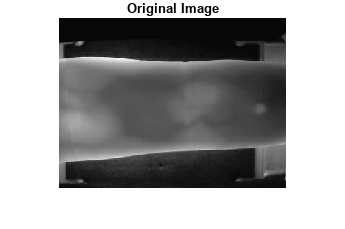

close all; clear; clc;
filename = input('Enter image filename with (" "): ');
Io = imread(filename);
imshow(Io)
title("Original Image")

### Grayscale Image

I = rgb2gray(Io);  %change to gray scale (2D image)

### Use Image segmentImage Function to Isolate Finger

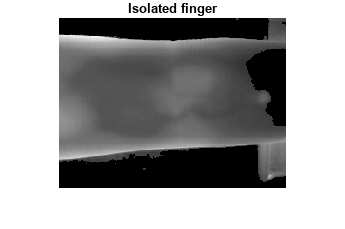

Resized_Image = imresize(I, [240 320]);
Is = segmentImage(Resized_Image);
title("Isolated finger")

### Sharpen Image

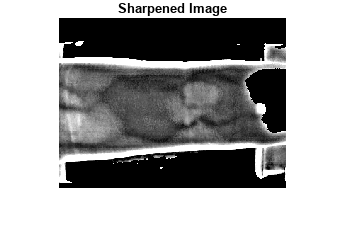

Ish = imsharpen(Is,'Radius',7,'Amount',7);
Ish(Ish<0.1) = 0;
imshow(Ish)
title("Sharpened Image")

### Find Veins by Thresholding

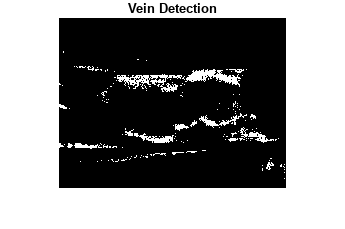

Iv = zeros(size(Ish));
[ll,ww] = size(Ish);
for l = 1:ll
    for w = 1:ww
        if Ish(l,w) == 0 || Ish(l,w) == 255
             Iv(l,w) = 0;
        else
            if Ish(l,w) < 52 
                Iv(l,w) = 255;
            else
                Iv(l,w) = 0;
            end
        end
 
    end
end

imshow(Iv)
title("Vein Detection")

Ish = im2uint8(Ish);

### Fill in the Gaps

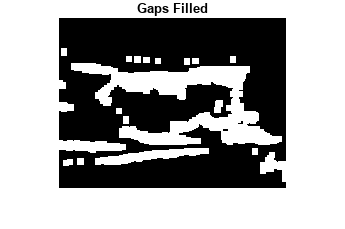

se90 = strel('line',3,90);
se0 = strel('line',3,0);
Iv = imdilate(Iv,[se90 se0]);
Iv = imfill(Iv,'holes');
Iv = imdilate(Iv,[se90 se0]);
Iv = imfill(Iv,'holes');
Iv = imdilate(Iv,[se90 se0]);
Iv = imfill(Iv,'holes');
Iv = imdilate(Iv,[se90 se0]);
Iv = imfill(Iv,'holes');
imshow(Iv)
title("Gaps Filled")

### Clean Image

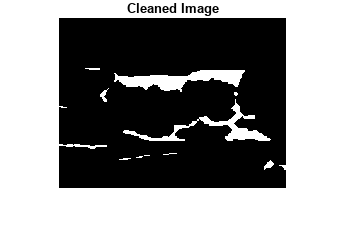

seD = strel('diamond',1);
Iv = imerode(Iv,seD);
Iv = imerode(Iv,seD);
Iv = imerode(Iv,seD);
Iv = imerode(Iv,seD);
Iv = imerode(Iv,seD);
Iv = imerode(Iv,seD);
imshow(Iv)
title("Cleaned Image")

### Display Vein on Original Image

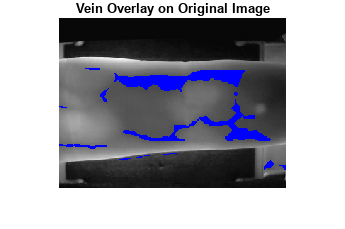

Ifinal = rgb2gray(Io);
Ifinal(Iv == 255) = 255;
Iv = cat(3, Iv, Iv, Iv);
Ifinal = cat(3, I, I, I);
[ll,ww,cc] = size(Ifinal);
for l = 1:ll
    for w = 1:ww
            if Iv(l,w,1) == 255 && Iv(l,w,2) == 255 && Iv(l,w,3) == 255
                Ifinal(l,w,1) = 0;
                Ifinal(l,w,2) = 0;
                Ifinal(l,w,3) = 255;
            end
    end

end
imshow(Ifinal)
title("Vein Overlay on Original Image")